This is a script for the SGD algorithm behaviour in \mu-strongly convex functions when a time-varying step size strategy is implemented. The Gradient Descent (GD), Stochastic Gradient Descent (SGD) and Averaging Stochastic Gradient Descent (ASGD) is investigated.

clear all; close all; clc;

% Generate the cost function and its gradient
syms x
rng("default")
x_min = sort(rand(5,1)*5);
x_coeff = sort(rand(5,1)+1);
cost_function1 = @(x) 0.2*x_coeff(1)*(x+x_min(1))^2;
cost_function2 = @(x) 0.2*x_coeff(2)*(x+x_min(2))^2;
cost_function3 = @(x) 0.2*x_coeff(3)*(x+x_min(3))^2;
cost_function4 = @(x) 0.2*x_coeff(4)*(x+x_min(4))^2;
cost_function5 = @(x) 0.2*x_coeff(5)*(x+x_min(5))^2;

gradient_function1 = str2func(['@(x)' char(diff(cost_function1,x)) ]);
gradient_function2 = str2func(['@(x)' char(diff(cost_function2,x)) ]);
gradient_function3 = str2func(['@(x)' char(diff(cost_function3,x)) ]);
gradient_function4 = str2func(['@(x)' char(diff(cost_function4,x)) ]);
gradient_function5 = str2func(['@(x)' char(diff(cost_function5,x)) ]);

% Parameters 
lambda = 2;
step_size = 1/lambda;
num_epochs = 100;
x_0 = [5]; % Initial guess
x_storage = [0,0,0,x_0,x_0;
    0,0,0,x_0,x_0;
    x_0,x_0,x_0,x_0,x_0,;];
f_0=cost_function1(x_0)+cost_function2(x_0)+cost_function3(x_0)+cost_function4(x_0)+cost_function5(x_0);
cost_storage = [f_0,f_0;
    f_0,f_0;
    f_0,f_0;];

% SGD loop
for epoch = 1:num_epochs

    % GD: Compute the gradient
    gradient = gradient_function1(x_storage(1,end)) + gradient_function2(x_storage(1,end))+ ...
    gradient_function3(x_storage(1,end))+gradient_function4(x_storage(1,end)) + ...
    gradient_function5(x_storage(1,end));
    % Update the parameter using one random gradient at each epoc
    % x_kp1 = x_k - \gamma_k * \nabla f_i (x_k)
    x_new_gd = x_storage(1,end) - step_size * gradient; 
    % Compute the current cost
    cost_gd = cost_function1(x_new_gd)+cost_function2(x_new_gd)+  ...
    cost_function3(x_new_gd)+cost_function4(x_new_gd)+ ...
    cost_function5(x_new_gd);


    % SGD: Compute the gradient
    switch mod(epoch,5)
        case 0
        gradient = gradient_function1(x_storage(2,end));
        case 1
        gradient = gradient_function2(x_storage(2,end));
        case 2
        gradient = gradient_function3(x_storage(2,end));
        case 3
        gradient = gradient_function4(x_storage(2,end));
        case 4
        gradient = gradient_function5(x_storage(2,end));
    end
    % Update the parameter using one random gradient at each epoc
    % x_kp1 = x_k - \gamma_k * \nabla f_i (x_k)
    x_new_rsgd = x_storage(2,end) - step_size * gradient; 
    % Compute the current cost
    cost_rsgd = cost_function1(x_new_rsgd)+cost_function2(x_new_rsgd)+  ...
    cost_function3(x_new_rsgd)+cost_function4(x_new_rsgd)+ ...
    cost_function5(x_new_rsgd);


    % ASGD: Compute the gradient
    switch mod(epoch,5)
        case 0
        gradient = gradient_function1(x_storage(3,end))+ ...
            gradient_function2(x_storage(3,end-4))+gradient_function3(x_storage(3,end-3))+...
            gradient_function4(x_storage(3,end-2))+gradient_function5(x_storage(3,end-1));
        case 1
        gradient = gradient_function1(x_storage(3,end-1))+ ...
            gradient_function2(x_storage(3,end))+gradient_function3(x_storage(3,end-4))+...
            gradient_function4(x_storage(3,end-3))+gradient_function5(x_storage(3,end-2));
        case 2
        gradient = gradient_function1(x_storage(end-2))+...
            gradient_function2(x_storage(end-1))+ gradient_function3(x_storage(3,end))+...
        gradient_function4(x_storage(3,end-4))+gradient_function5(x_storage(3,end-3));
        case 3
        gradient = gradient_function1(x_storage(3,end-3))+ ...
            gradient_function2(x_storage(3,end-2))+gradient_function3(x_storage(3,end-1))+...
            gradient_function4(x_storage(3,end))+gradient_function5(x_storage(3,end-4));
        case 4
        gradient = gradient_function1(x_storage(3,end-4))+ ...
            gradient_function2(x_storage(3,end-3))+gradient_function3(x_storage(3,end-2))+...
            gradient_function4(x_storage(3,end-1))+gradient_function5(x_storage(3,end));
    end
    % Update the parameter using one random gradient and half step at each epoc
    % x_kp1 = x_k - \gamma_k/2 * (\nabla f_1 (x_k) + \nabla f_2 (x_k))
    x_new_asgd = x_storage(3,end) - step_size/5 * gradient; 
    % Compute the current cost
    cost_asgd = cost_function1(x_new_asgd)+cost_function2(x_new_asgd)+  ...
    cost_function3(x_new_asgd)+cost_function4(x_new_asgd)+ ...
    cost_function5(x_new_asgd);

    % Storage the trajectory
    cost_storage = [cost_storage, [cost_gd;cost_rsgd;cost_asgd;]];
    x_storage = [x_storage, [x_new_gd;x_new_rsgd;x_new_asgd;]];
    step_size = 1/(lambda*epoch);
end


figure

% Plot the cost function
h = fplot(@(x) 0.2*x_coeff(1)*(x+x_min(1))^2 + 0.2*x_coeff(2)*(x+x_min(2))^2 + ...
    0.2*x_coeff(3)*(x+x_min(3))^2 + 0.2*x_coeff(4)*(x+x_min(4))^2+ ...
    0.2*x_coeff(5)*(x+x_min(5))^2, [-10, 5],'k');

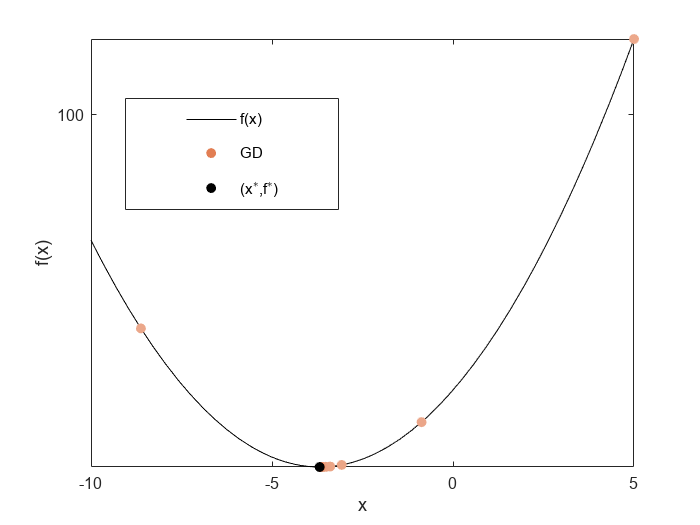

hold on;

% Mark the minimum point found by GD

map = interpolate(stateSpaceSE2,[1,1,1],[0.8500 0.3250 0.0980],0.5:0.5/(epoch+1):1);
scatter(x_storage(1,4:end),cost_storage(1,:),[],map,'filled')

[yopt,imx]=min(h.YData); % find minimum
xopt=h.XData(imx);
scatter(xopt,yopt,'k','filled')
xlim([-10,5])
xlabel('x');
ylabel('f(x)');
% title('Minimizing f(x) as sum of absolute functions with step size \gamma = 0.1');
legend("f(x)","GD","(x^{\ast},f^{\ast})")
legend("Position", [0.17802,0.60054,0.3066,0.21226])
yticks([0 100])
xticks([-10 -5 0 5])
saveas(gcf,'quad_decreasing1.svg')
saveas(gcf,'quad_decreasing1.png')



figure

% Plot the cost function
h = fplot(@(x) 0.2*x_coeff(1)*(x+x_min(1))^2 + 0.2*x_coeff(2)*(x+x_min(2))^2 + ...
    0.2*x_coeff(3)*(x+x_min(3))^2 + 0.2*x_coeff(4)*(x+x_min(4))^2+ ...
    0.2*x_coeff(5)*(x+x_min(5))^2, [-10, 5],'k');

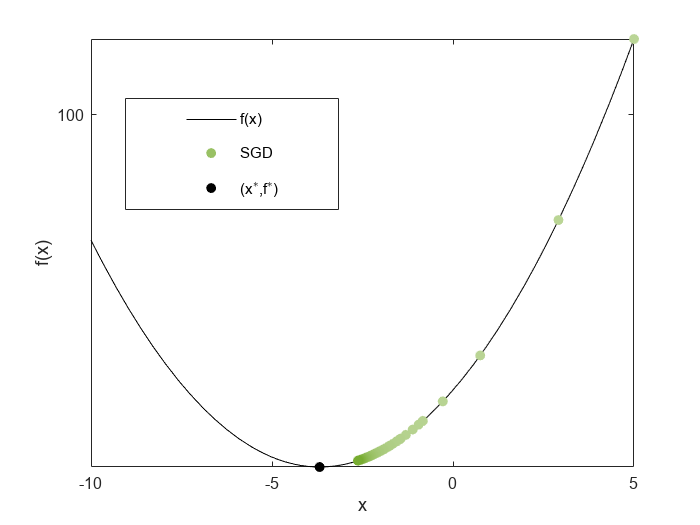

hold on;

% Mark the minimum point found by GD
map = interpolate(stateSpaceSE2,[1,1,1],[0.4660 0.6740 0.1880],0.5:0.5/(epoch+1):1);
scatter(x_storage(2,4:end),cost_storage(2,:),[],map,'filled')

[yopt,imx]=min(h.YData); % find minimum
xopt=h.XData(imx);
scatter(xopt,yopt,'k','filled')
xlim([-10,5])
xlabel('x');
ylabel('f(x)');
% title('Minimizing f(x) as sum of absolute functions with step size \gamma = 0.1');
legend("f(x)","SGD","(x^{\ast},f^{\ast})")
legend("Position", [0.17802,0.60054,0.3066,0.21226])
yticks([0 100])
xticks([-10 -5 0 5])
saveas(gcf,'quad_decreasing2.svg')
saveas(gcf,'quad_decreasing2.png')



figure

% Plot the cost function
h = fplot(@(x) 0.2*x_coeff(1)*(x+x_min(1))^2 + 0.2*x_coeff(2)*(x+x_min(2))^2 + ...
    0.2*x_coeff(3)*(x+x_min(3))^2 + 0.2*x_coeff(4)*(x+x_min(4))^2+ ...
    0.2*x_coeff(5)*(x+x_min(5))^2, [-10, 5],'k');

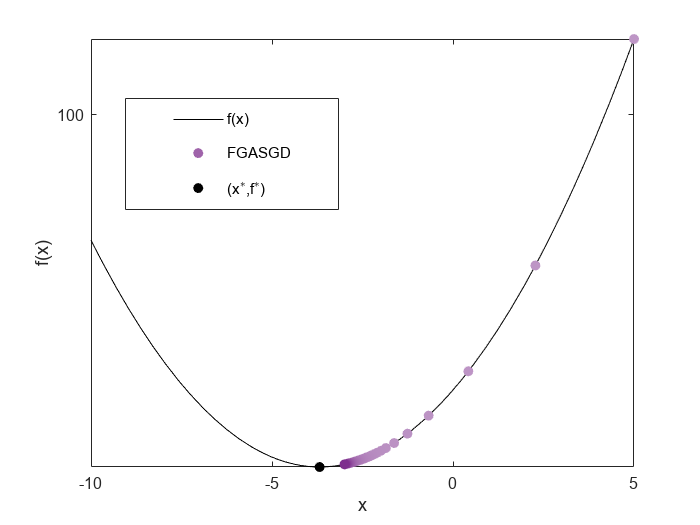

hold on;

% Mark the minimum point found by GD
map = interpolate(stateSpaceSE2,[1,1,1],[0.4940 0.1840 0.5560],0.5:0.5/(epoch+1):1);
scatter(x_storage(3,4:end),cost_storage(3,:),[],map,'filled')
[yopt,imx]=min(h.YData); % find minimum
xopt=h.XData(imx);
scatter(xopt,yopt,'k','filled')
xlim([-10,5])
xlabel('x');
ylabel('f(x)');
% title('Minimizing f(x) as sum of absolute functions with step size \gamma = 0.1');
legend("f(x)","FGASGD","(x^{\ast},f^{\ast})")
legend("Position", [0.17802,0.60054,0.3066,0.21226])
yticks([0 100])
xticks([-10 -5 0 5])
saveas(gcf,'quad_decreasing3.svg')
saveas(gcf,'quad_decreasing3.png')

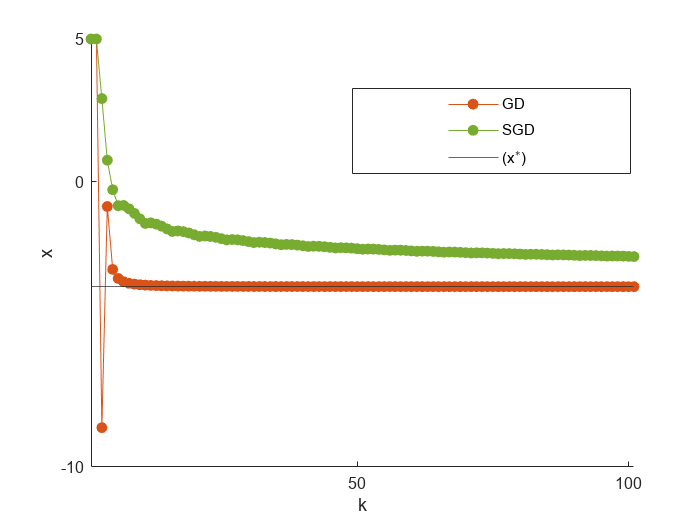


figure
hold on;
% Mark the minimum point found by GD
h1=plot(1:epoch+2, x_storage(1,4:end),'-o','color',"#D95319");set(h1, 'MarkerFaceColor', "#D95319");
h2=plot(1:epoch+2, x_storage(2,4:end),"-o",'color',"#77AC30");set(h2, 'MarkerFaceColor', "#77AC30");
% h3=plot(1:epoch+2, x_storage(3,4:end),"-o",'color',"#7E2F8E");set(h3, 'MarkerFaceColor', "#7E2F8E");
xlabel('k');
ylabel('x');
yline(xopt)
legend("GD","SGD","(x^{\ast})")
xlim([1,epoch+1])
legend("Position", [0.50335,0.66858,0.39788,0.16432])
xticks([0 50 100])
yticks([-10 0 5])
saveas(gcf,'quad_decreasing4.svg')
saveas(gcf,'quad_decreasing4.png')

save SGD_quad_decreasing.mat
